## Simulink

Parametres from Cheng

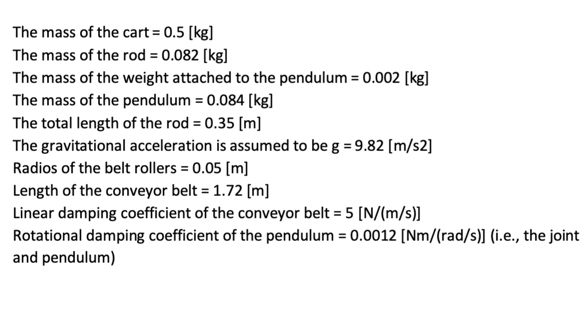

m_c = 0.5;      % Mass of cart [kg]
m_p = 0.083;    % Mass of pendulum [kg]
l = 0.357;      % Length of pendulum [m]
g = 9.81;       % Gravitational acceleration [m/s^2]
b_c = 5;        % Linear damping coefficient of the cart [N/(m/s)]
b_p = 0.0012;   % Rotational damping coefficient of the pendulum [Nm/(rad/s)
I = (1/3)*m_p*l^2;     % inertia of pendulum



function [xdd, thetadd] = fcn(m_c, m_p, l, b_c, b_p, I, g, xd, x, thetad, theta, F)

% Masse-matrix
M = [m_c + m_p,  mp*l*cos(theta);
     m_p * l * cos(theta), mp * l^2 + I]
M_inv = inv(M)

% Højre side af ligningen
RHS = [F - b_c * xd + m_p * l * sin(theta) * thetad^2;
       -b_p * thetad - mp*g*l*sin(theta)]

a = M_inv*RHS

xdd = a(1)
thetadd = a(2)


end

## Isolering af ddx og ddtheta

% Symbolsk variabler
syms mc mp l theta thetad thetadd x xd xdd I bc bp g F

% Masse-matrix
M = [mc + mp,  mp*l*cos(theta);
     mp*l*cos(theta), mp*l^2 + I];
M_inv = inv(M);

% Højre side af ligningen
RHS = [F - bc*xd + mp*l*sin(theta)*thetad^2;
       -bp*thetad - mp*g*l*sin(theta)];

a = M_inv*RHS

$$a = \begin{array}{l} \left(\begin{array}{c} \frac{\left(\mathrm{mp}\,l^{2}+\text{I}\right)\,\sigma_{2}}{\sigma_{1}}+\frac{l\,\mathrm{mp}\,\cos\left(\theta \right)\,\left(\mathrm{bp}\,\mathrm{thetad}+g\,l\,\mathrm{mp}\,\sin\left(\theta \right)\right)}{\sigma_{1}}\\ -\frac{\left(\mathrm{bp}\,\mathrm{thetad}+g\,l\,\mathrm{mp}\,\sin\left(\theta \right)\right)\,\left(\mathrm{mc}+\mathrm{mp}\right)}{\sigma_{1}}-\frac{l\,\mathrm{mp}\,\cos\left(\theta \right)\,\sigma_{2}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-l^{2}\,{\mathrm{mp}}^{2}\,{\cos\left(\theta \right)}^{2}+l^{2}\,{\mathrm{mp}}^{2}+\mathrm{mc}\,l^{2}\,\mathrm{mp}+\text{I}\,\mathrm{mp}+\text{I}\,\mathrm{mc}\\ \sigma_{2}=l\,\mathrm{mp}\,\sin\left(\theta \right)\,{\mathrm{thetad}}^{2}+F-\mathrm{bc}\,\mathrm{xd} \end{array}$$

simplifiedExpr = simplify(a)

$$simplifiedExpr = \begin{array}{l} \left(\begin{array}{c} \frac{F\,\text{I}-\text{I}\,\mathrm{bc}\,\mathrm{xd}+F\,l^{2}\,\mathrm{mp}-\mathrm{bc}\,l^{2}\,\mathrm{mp}\,\mathrm{xd}+l^{3}\,{\mathrm{mp}}^{2}\,{\mathrm{thetad}}^{2}\,\sin\left(\theta \right)+g\,l^{2}\,{\mathrm{mp}}^{2}\,\cos\left(\theta \right)\,\sin\left(\theta \right)+\text{I}\,l\,\mathrm{mp}\,{\mathrm{thetad}}^{2}\,\sin\left(\theta \right)+\mathrm{bp}\,l\,\mathrm{mp}\,\mathrm{thetad}\,\cos\left(\theta \right)}{\sigma_{1}}\\ -\frac{\mathrm{bp}\,\mathrm{mc}\,\mathrm{thetad}+\mathrm{bp}\,\mathrm{mp}\,\mathrm{thetad}+F\,l\,\mathrm{mp}\,\cos\left(\theta \right)+g\,l\,{\mathrm{mp}}^{2}\,\sin\left(\theta \right)+l^{2}\,{\mathrm{mp}}^{2}\,{\mathrm{thetad}}^{2}\,\cos\left(\theta \right)\,\sin\left(\theta \right)-\mathrm{bc}\,l\,\mathrm{mp}\,\mathrm{xd}\,\cos\left(\theta \right)+g\,l\,\mathrm{mc}\,\mathrm{mp}\,\sin\left(\theta \right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-l^{2}\,{\mathrm{mp}}^{2}\,{\cos\left(\theta \right)}^{2}+l^{2}\,{\mathrm{mp}}^{2}+\mathrm{mc}\,l^{2}\,\mathrm{mp}+\text{I}\,\mathrm{mp}+\text{I}\,\mathrm{mc} \end{array}$$

disp('----------------------------------------------------------')

----------------------------------------------------------


## State space -> transfer function

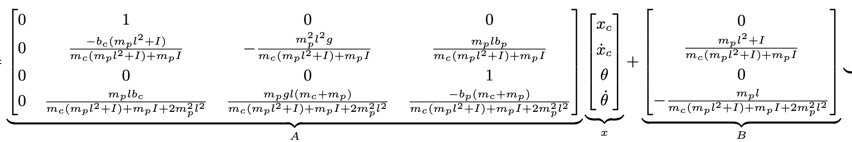

- Når du skubber vognen til højre, vil pendulet “hænge efter” og dermed vinkle mod venstre.

- Derfor bliver `B(4)` negativ i den lineariserede model omkring den **oprejste** position (`theta ≈ 0`).

clc; clear; close all;

m_c = 0.5;      % Mass of cart [kg]
m_p = 0.083;    % Mass of pendulum [kg]
l = 0.357;      % Length of pendulum [m]
g = 9.81;       % Gravitational acceleration [m/s^2]
b_c = 5;        % Linear damping coefficient of the cart [N/(m/s)]
b_p = 0.0012;   % Rotational damping coefficient of the pendulum [Nm/(rad/s)
I = (1/3)*m_p*l^2;     % inertia of pendulum

den1 = (m_c*(m_p*l^2 + I) + m_p*I);
den2 = den1+2*m_p^2*l^2;

% Definer matricer
A = [0, 1, 0, 0;
     0, (-b_c * (m_p*l^2 + I)) / den1, (m_p^2*l^2*g)/den1, (m_p*l*b_p)/den1;
     0, 0, 0, 1;
     0, (m_p*l*b_c)/den2, (m_p*g*l*(m_c + m_p))/den2, (-b_p*(m_c + m_p))/den2];
%disp(A)

B = [ 0;
     (m_p*l^2 + I) / den1; % input kraft påvirker cart positivt
      0;
      -(m_p*l) / den2 ]; % input kraft påvirker pendulet negativt
%disp(B)

C = [1 0 0 0;
     0 0 1 0];

D = [0; 0];

% transfer functions
[b,a] = ss2tf(A,B,C,D);

% both systems
Gx = tf(b(1,:), a(1,:))


Gx =
 
       1.92 s^2 + 0.1319 s - 39.58
  -------------------------------------
  s^4 + 9.678 s^3 - 17.96 s^2 - 197.9 s
 
Continuous-time transfer function.
Model Properties


GTheta = tf(b(2,:), a(1,:))


GTheta =
 
  -3.256 s^2 - 1.344e-14 s - 3.929e-16
  -------------------------------------
  s^4 + 9.678 s^3 - 17.96 s^2 - 197.9 s
 
Continuous-time transfer function.
Model Properties


## Root locus, step/impulsresponse

disp('----------------------------------------------------------')

----------------------------------------------------------


disp('Root locus, step/impulsresponse')

Root locus, step/impulsresponse


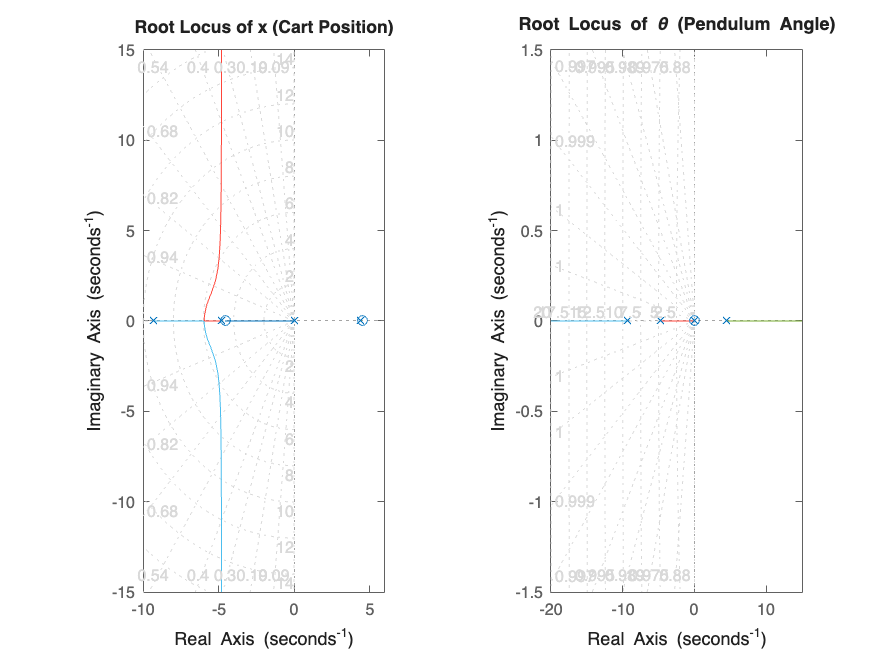

% andet test
% Antag at x og theta er overføringsfunktioner (transfer functions)

% ROOT LOCUS PLOTS
figure('Name','Root Locus','NumberTitle','off')
subplot(1,2,1)
rlocus(Gx)
title('Root Locus of x (Cart Position)')
xlabel('Real Axis'), ylabel('Imaginary Axis')
grid on

subplot(1,2,2)
rlocus(GTheta)
title('Root Locus of \theta (Pendulum Angle)')
xlabel('Real Axis'), ylabel('Imaginary Axis')
grid on

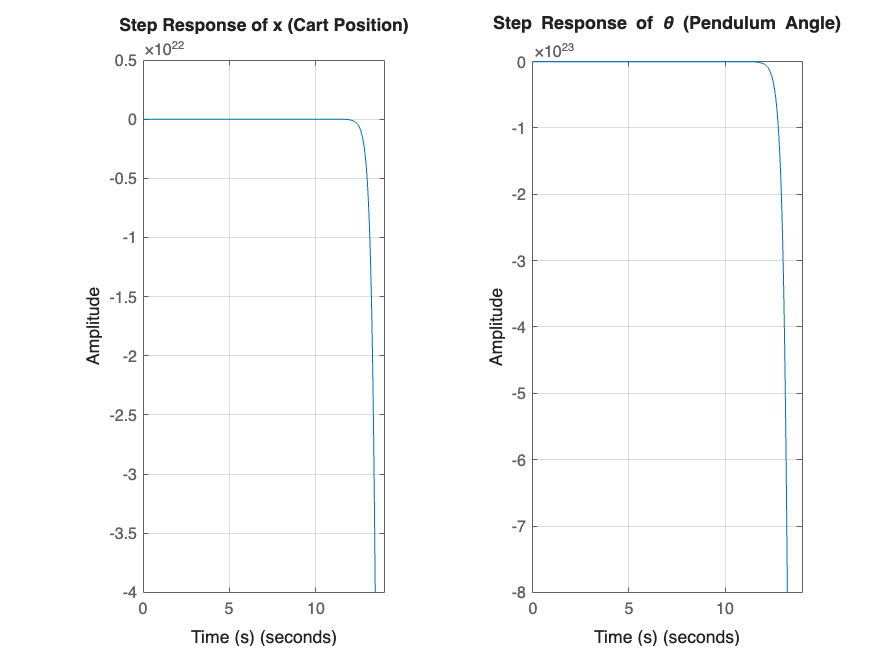


% STEP RESPONSES
figure('Name','Step Response','NumberTitle','off')
subplot(1,2,1)
step(Gx)
title('Step Response of x (Cart Position)')
xlabel('Time (s)'), ylabel('Amplitude')
grid on

subplot(1,2,2)
step(GTheta)
title('Step Response of \theta (Pendulum Angle)')
xlabel('Time (s)'), ylabel('Amplitude')
grid on

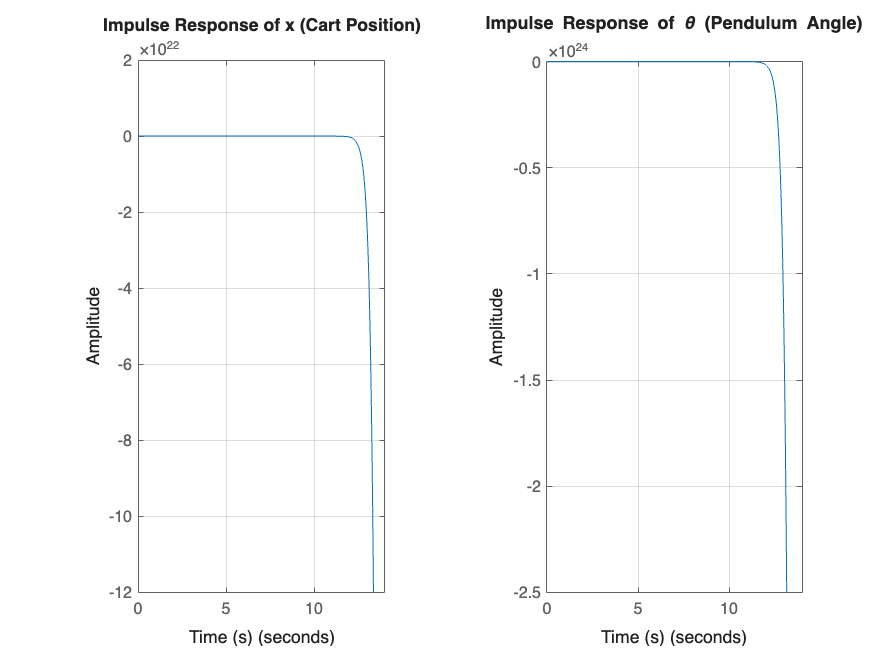


% IMPULSE RESPONSE (kun x)
figure('Name','Impulse Response','NumberTitle','off')
subplot(1,2,1)
impulse(Gx)
title('Impulse Response of x (Cart Position)')
xlabel('Time (s)'), ylabel('Amplitude')
grid on

subplot(1,2,2)
impulse(GTheta)
title('Impulse Response of \theta (Pendulum Angle)')
xlabel('Time (s)'), ylabel('Amplitude')
grid on

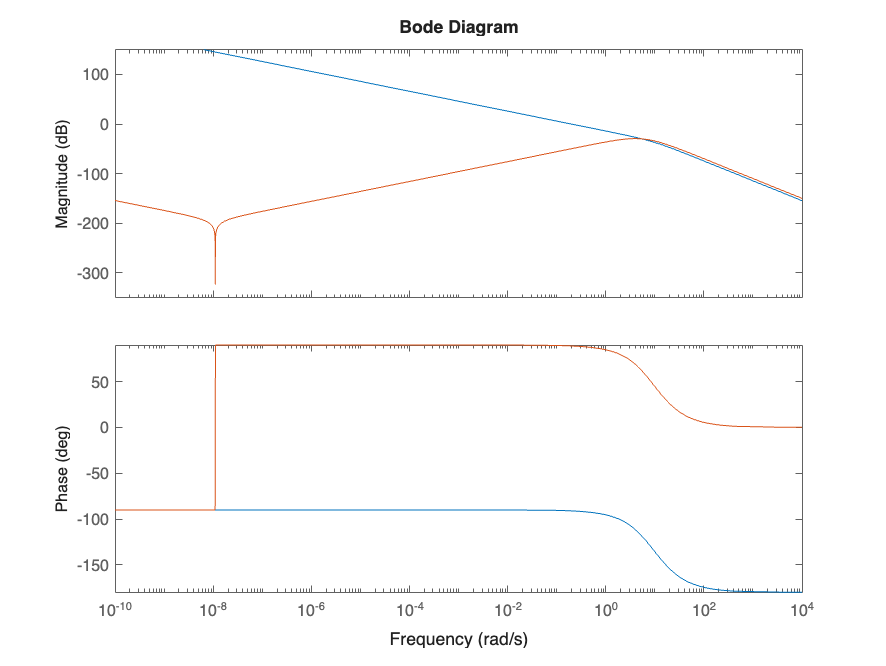


figure
bode(Gx, GTheta)

%nyquist(Gx)

eig(A)

ans =          0
   -9.3305
   -4.7824
    4.4345



% controlable
mc = [B, A*B, A^(2)*B, A^(3)*B]

mc = 1.0e+03 *

         0    0.0019   -0.0185    0.1735
    0.0019   -0.0185    0.1735   -1.6308
         0   -0.0033    0.0315   -0.3635
   -0.0033    0.0315   -0.3635    3.4395


det(mc) % når determinanten er forskellig fra 0, så er systemet controlable

ans = 1.6603e+04

## Perfomance specifikation

disp('----------------------------------------------------------')

----------------------------------------------------------


disp('Perfomance specification')

Perfomance specification




tr = 0.6; % rise time (<0.3)
ts = 3; % settling time (<3)
Mp = 10; % overshoot (<7%)


alpha_percentage = 4 % settling time

alpha_percentage = 4



omega_n = 1.8/tr % natural frequency

omega_n = 3

zeta = sqrt((log(Mp) / -pi)^2 / (1 + (log(Mp) / -pi)^2)) % needs to be smaller than Mp

zeta = 0.5912

sigma = (-log(alpha_percentage/100))/ts

sigma = 1.0730

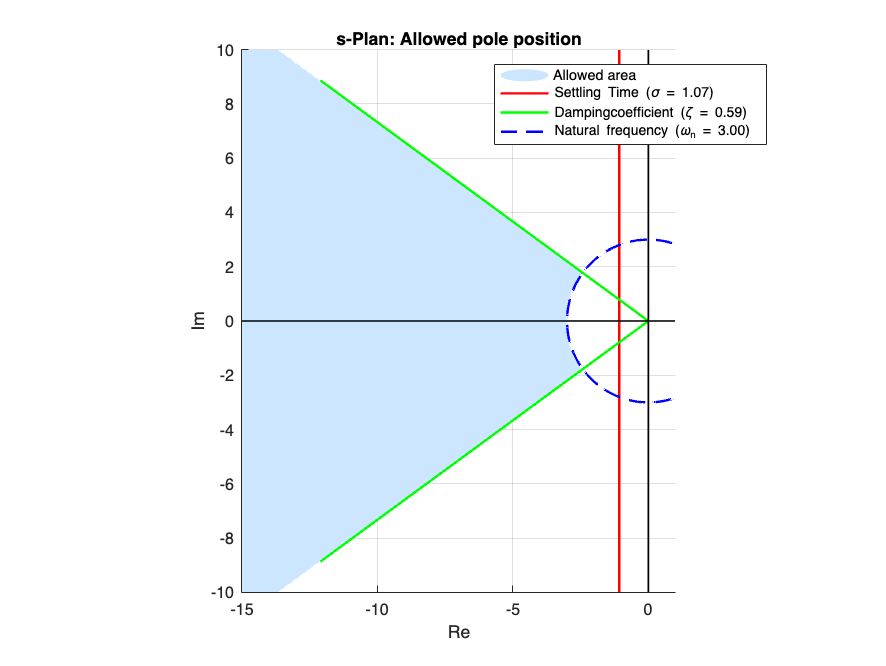




% ---------------------- figur -------------------
% Beregn vinkel
theta = asin(zeta);

% Ny grænse for real-akse
xMin = -15;
xMax = 1;
yMin = -10;
yMax = 10;

% Opret gitter
re = linspace(xMin, xMax, 300);
im = linspace(yMin, yMax, 400);
[Re, Im] = meshgrid(re, im);
S = Re + 1i * Im;

% Krav
settling = real(S) <= -sigma;
angle = abs(imag(S) ./ real(S)) <= tan(theta) & real(S) <= 0;
rise = abs(S) >= omega_n;
combined = settling & angle & rise;

figure;
hold on;
grid on;
axis equal;

% Plot tilladt område (kombineret constraint): lyseblå uden kant
fill_region = contourf(Re, Im, combined, [1 1], 'FaceColor', [0.8 0.9 1], ...
    'EdgeColor', 'none', 'DisplayName','Allowed area');
alpha(0.5);

% Settling time-linje (σ): Rød
plot([-sigma -sigma], [yMin yMax], 'r-', 'LineWidth', 1.5, ...
    'DisplayName', sprintf('Settling Time (\\sigma = %.2f)', sigma));

% Dæmpningslinjer (ζ): Grøn
r = abs(xMin);
plot([0 -r*cos(theta)], [0 r*sin(theta)], 'g-', 'LineWidth', 1.5, ...
    'DisplayName', sprintf('Dampingcoefficient (\\zeta = %.2f)', zeta));
plot([0 -r*cos(theta)], [0 -r*sin(theta)], 'g-', 'LineWidth', 1.5, 'HandleVisibility','off');

% Rise time cirkel (ωₙ): Blå streg
theta_circle = linspace(0, 2*pi, 200);
plot(omega_n*cos(theta_circle), omega_n*sin(theta_circle), 'b--', 'LineWidth', 1.5, ...
    'DisplayName', sprintf('Natural frequency (\\omega_n = %.2f)', omega_n));

% Akser (sort, men ikke vist i legend)
plot([xMin xMax], [0 0], 'k-', 'LineWidth', 1, 'HandleVisibility','off'); % Re-akse
plot([0 0], [yMin yMax], 'k-', 'LineWidth', 1, 'HandleVisibility','off'); % Im-akse

% Labels og titel
xlabel('Re');
ylabel('Im');
title('s-Plan: Allowed pole position');
legend('show', 'Location', 'best');

% Skala
xlim([xMin xMax]);
ylim([yMin yMax]);

hold off;

## Sæt poler til venstre for perfomance specification

### Theta - pendulum

Ændre $K_p \;K_i \;\textrm{og}\;K_d$ og se på root locus om polerne har ændret sig, evt brug "pole" og se om nogle poler ligger på den positive del af reelplanen.

$K_p$: øger systemets respons, men kan forværre ustabilitet, hvis for høj

$K_i$: Flytter poler væk fra imaginæraksen og kan introducere ekstra poler nær oprindelsen, men for høj, kan forværre ustabilitet.

$K_d$: Tilføjer dæmpning og flytter poler længere ind i venstre halvplan, men for høj, kan gøre systemet for stift.

Lineariseret model har man et negativt forhold mellem input og output. -> Når man giver vognen en kraft i POSITIV x-retning, så vil pendulet svinge til venstre (ved oprejst position), dsv. output af pendulet bevæger sig NEGATIVT i x-retning.

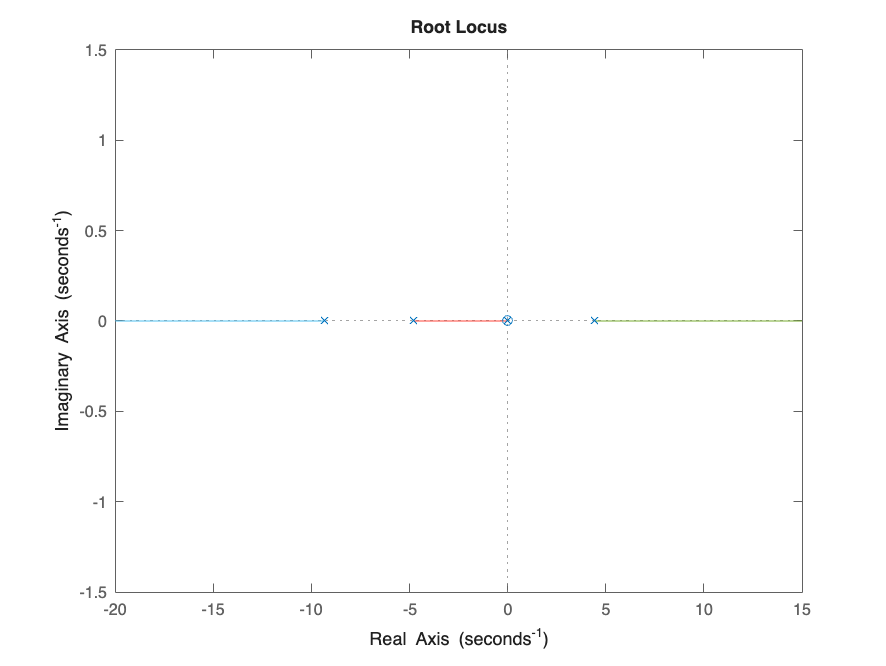

G = GTheta; % åbent sløjfe
rlocus(GTheta)

pole(GTheta)

ans =          0
    4.4345
   -9.3305
   -4.7824


zero(GTheta)

ans = 1.0e-07 *

  -0.0000 + 0.1099i
  -0.0000 - 0.1099i



% efter valg af nye nuller
s = tf('s')


s =
 
  s
 
Continuous-time transfer function.
Model Properties


con = (s+1)*(s+5)/s % kp = 1, ki = 6, kd = 5


con =
 
  s^2 + 6 s + 5
  -------------
        s
 
Continuous-time transfer function.
Model Properties


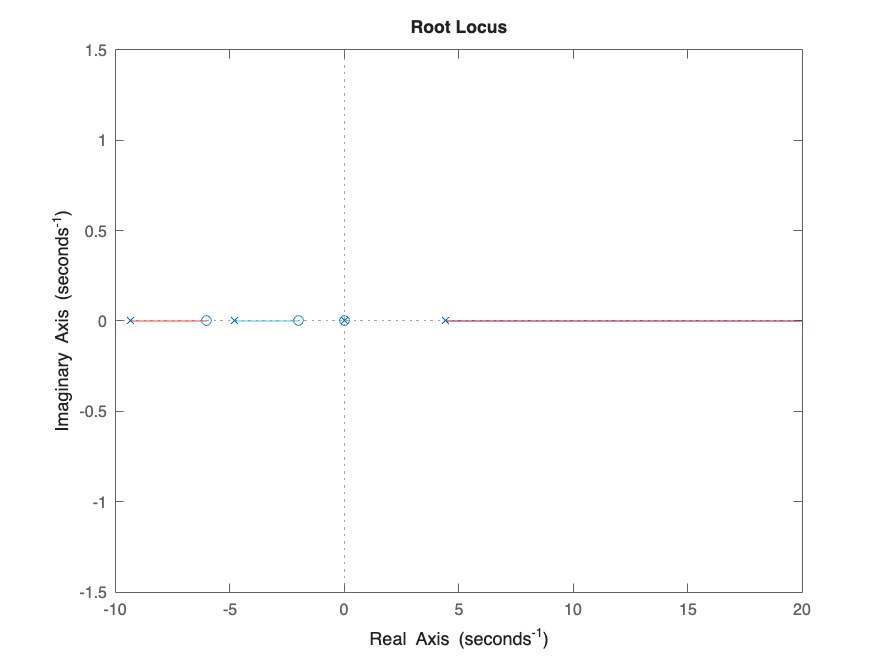

con = (s + 2)*(s + 6)/s;   % lead / lag - ekstra pol tæt på origo

rlocus(con*GTheta)

%rltool(con*GTheta)
pole(con*GTheta)

ans =          0
         0
    4.4345
   -9.3305
   -4.7824


zero(con*GTheta)

ans =   -6.0000 + 0.0000i
  -2.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 - 0.0000i




% sæt K-værdier ud fra transfer function
[num, den] = tfdata(con, 'v');  % Få tæller og nævner som vektorer
Kd = num(1)        % koefficient for s^2

Kd = 1

Kp = num(2)        % koefficient for s

Kp = 8

Ki = num(3)        % konstantled

Ki = 12


K = Kp

K = 8

Ti = K/Ki

Ti = 0.6667

Td = Kd/K

Td = 0.1250


K = 75 % ændre denne værdi

K = 75

con = K*(1+1/(Ti*s)+Td*s)


con =
 
  6.25 s^2 + 50 s + 75
  --------------------
        0.6667 s
 
Continuous-time transfer function.
Model Properties


% sæt K-værdier ud fra transfer function
[num, den] = tfdata(con, 'v');  % Få tæller og nævner som vektorer
Kd = num(1)        % koefficient for s^2

Kd = 6.2500

Kp = num(2)        % koefficient for s

Kp = 50

Ki = num(3)        % konstantled

Ki = 75


T_cl = feedback(con*G, 1) % closed loop


T_cl =
 
       -20.35 s^4 - 162.8 s^3 - 244.2 s^2 - 1.028e-12 s - 2.947e-14
  -----------------------------------------------------------------------
  0.6667 s^5 - 13.9 s^4 - 174.8 s^3 - 376.1 s^2 - 1.028e-12 s - 2.947e-14
 
Continuous-time transfer function.
Model Properties


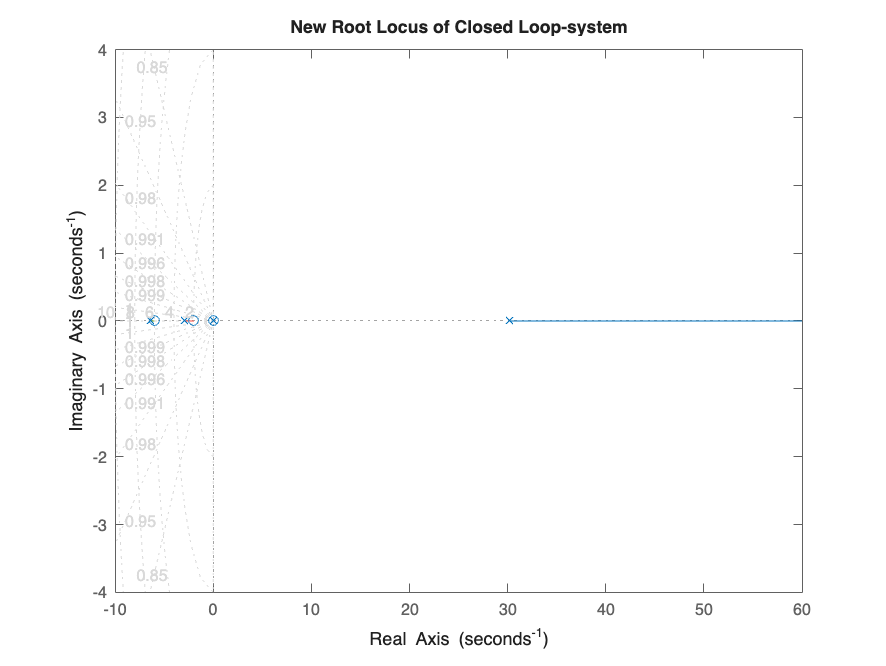

% Plot rodsted (root locus)
figure;
rlocus(T_cl)
title('New Root Locus of Closed Loop-system')
grid on


% Udskriv poler
newPoles = pole(T_cl);
disp('--- Poles in closed loop G(s) ---')

--- Poles in closed loop G(s) ---


disp(newPoles)

  30.1581 + 0.0000i
  -6.3814 + 0.0000i
  -2.9315 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 - 0.0000i




% Udskriv nulpunkter
newZeroes = zero(T_cl);
disp('--- Zeroes in closed loop G(s) ---')

--- Zeroes in closed loop G(s) ---


disp(newZeroes)

  -6.0000 + 0.0000i
  -2.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 - 0.0000i

